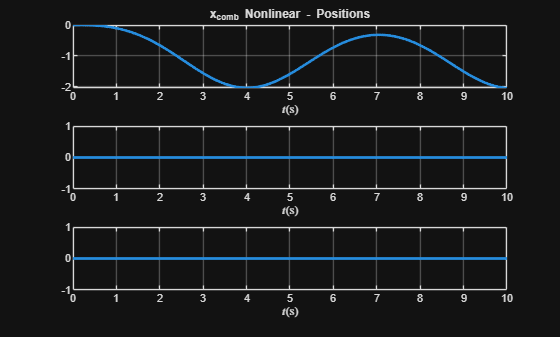

nx_rb = 6;
nx_fans = fanModelOrder*2;
nx_comb = nx_rb + nx_fans;

nu = 2;

sysdt_rb = c2d(sys_rb, Ts, 'zoh');
sysdt_comb = c2d(sys_comb, Ts, 'zoh');

Ad_rb = sysdt_rb.A;
Bd_rb = sysdt_rb.B;

Ad_fans = sysdt_fans.A;
Bd_fans = sysdt_fans.B;

Ad_comb = sysdt_comb.A;
Bd_comb = sysdt_comb.B;

tsim = 10; % Simulation time (s)
nsim = round(tsim / Ts); % Simulation steps

% Set up separate logs for each model (linear/nonlinear)
x_rb_log_li = zeros(nx_rb, nsim);
x_rb_log_nl = zeros(nx_rb, nsim);
u_rb_log_li = zeros(nu, nsim);
u_rb_log_nl = u_rb_log_li;

x_fans_log = zeros(nx_fans, nsim); % Only linear model
u_fans_log = zeros(nu, nsim);

x_comb_log_li = zeros(nx_comb, nsim);
x_comb_log_nl = zeros(nx_comb, nsim);
u_comb_log_li = zeros(nu, nsim);
u_comb_log_nl = u_comb_log_li;

tt_log = linspace(0, tsim, nsim);

% Initial conditions
x0_rb_li = zeros(nx_rb, 1);
x0_rb_nl = x0_rb_li;

x0_fans_li = zeros(nx_fans, 1);
x0_fans_nl = x0_fans_li;

x0_comb_li = [zeros(nx_rb, 1); 0; 0; zeros(nx_fans-2, 1)];
x0_comb_nl = [zeros(nx_rb, 1); F_e_real; F_e_real; zeros(nx_fans-2, 1)];

% Equilibrium conditions of each model (fan forces)
u_f_eq_li = [0; 0];
u_f_eq_nl = F_e_real + u_f_eq_li;

% Set fan force const inputs
u_f_li = -0.01*ones(2, 1);
% u_f_li = [F_e_real; F_e_real];
% u_f_li = [0.0; 0.0];
% u_f_nl = u_f_li + F_e_real;
% u_f_nl = u_f_li;
u_f_nl = u_f_li + F_e_real;
% u_f_li = u_f_eq_li;
% u_f_nl = u_f_eq_nl;

% LUT to find voltage for steady state fan force
u_v_li = u_f_li/k_fan;
u_v_nl = (F_e_real+u_f_li)/k_fan;
% u_v_nl = arrayfun(@FanSteadyStateLUT, u_f_nl);

% Simulate
for i = 1:nsim
    x0_rb_li = Ad_rb * x0_rb_li + Bd_rb * u_f_li;
    x0_rb_nl = model_nlRK4(f_rb_nl_handle, x0_rb_nl, u_f_nl, Ts);

    x0_fans_li = Ad_fans * x0_fans_li + Bd_fans * u_v_li;
    
    x0_comb_li = Ad_comb * x0_comb_li + Bd_comb * u_v_li;
    x0_comb_nl = model_nlRK4(f_comb_nl_handle, x0_comb_nl, u_v_nl, Ts);


    x_rb_log_li(:, i) = x0_rb_li;
    x_rb_log_nl(:, i) = x0_rb_nl;
    x_fans_log(:, i) = x0_fans_li;
    x_comb_log_li(:, i) = x0_comb_li;
    x_comb_log_nl(:, i) = x0_comb_nl;

    u_rb_log_li(:, i) = u_f_li;
    u_rb_log_nl(:, i) = u_f_nl;
    u_comb_log_li(:, i) = u_v_li;
    u_comb_log_nl(:, i) = u_v_nl;
end

% Plot results
% plotTimeseries(tt_log, x_fans_log(1:2, :), 'Title', 'Fan Response')


% plotTimeseries(tt_log, x_rb_log_li(1:3, :), 'Title', 'x_{rb} Linear - Positions')
plotTimeseries(tt_log, x_rb_log_nl(1:3, :), 'Title', 'x_{rb} Nonlinear - Positions')

% plotTimeseries(tt_log, x_rb_log_li(4:6, :), 'Title', 'x_{rb} Linear - Velocities')
% plotTimeseries(tt_log, x_rb_log_nl(4:6, :), 'Title', 'x_{rb} Nonlinear - Velocities')

% plotTimeseries(tt_log, x_rb_log_nl(1:3, :), 'Title', 'x_{rb} Nonlinear - Positions')
% plotTimeseries(tt_log, x_comb_log_li(1:3, :), 'Title', 'x_{comb} Linear - Positions')
% plotTimeseries(tt_log, x_comb_log_li(7:8, :), 'Title', 'x_{comb} - Fan Forces')
plotTimeseries(tt_log, x_comb_log_nl(1:3, :), 'Title', 'x_{comb} Nonlinear - Positions')

% plotTimeseries(tt_log, u_rb_log_nl, 'Title', 'x_{rb} - Fan Force Inputs')
% plotTimeseries(tt_log, x_comb_log_nl(7:8, :), 'Title', 'x_{comb} - Fan Forces')

% plotTimeseries(tt_log, x_comb_log_li(4:6, :), 'Title', 'x_{comb} Linear - Velocities')
% plotTimeseries(tt_log, x_comb_log_nl(4:6, :), 'Title', 'x_{comb} Nonlinear - Velocities')